# Cruise Control: System Analysis

Key MATLAB commands used in this tutorial are:  [`step`](http://www.mathworks.com/help/toolbox/control/ref/step.html),  [`stepinfo`](http://www.mathworks.com/help/toolbox/control/ref/stepinfo.html) 

## System model and parameters

The transfer function model for the automobile plant for the Cruise Control problem is given below. Please see the [Cruise Control: System Modeling](http://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=SystemModeling) page for the derivation.


$$
P(s) = \frac{V(s)}{U(s)} = \frac{1}{ms+b}  \qquad  [ \frac{m/s}{N} ]
$$


The parameters used in this example are as follows: 

## Performance specifications

The next step in our process is to select **design criteria** that the compensated system should achieve. When the vehicle drivetrain generates a 500-Newton force at the road-tire interface, the car will reach a maximum velocity of 10 m/s (22 mph). Observe the open-loop step response in the following section. In this application, we choose that the automobile should be able to achieve this speed within plus or minus 2%, while maintaining a maximum percent overshoot of less than 10%. Furthemore, we will require that the vehicle will have a rise time of less than 5 seconds. Here rise time corresponds to the time it takes the vehicle to increase its speed from 10% to 90% of its final value.

To summarize, we have proposed the following design criteria for this problem:

- Rise time < 5 s

- Overshoot < 10%

- Steady-state error < 2%

## Open-loop step response

The **open-loop** response of the system, without any feedback control, to a step input force of 500 Newtons is simulated in MATLAB as follows:

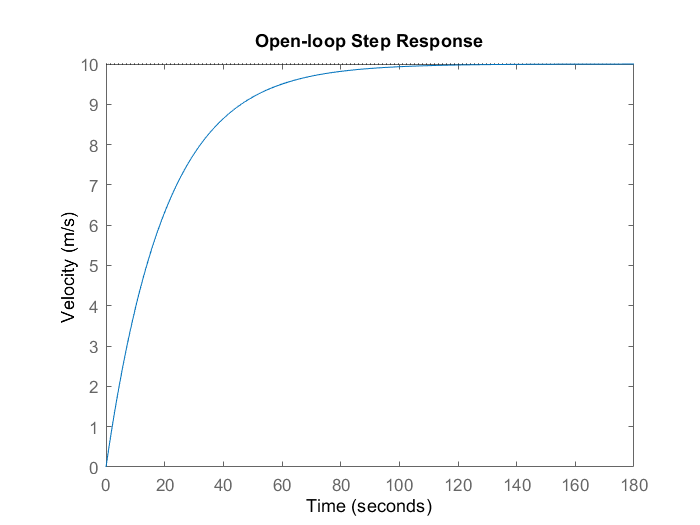

m = 1000;
b = 50;
u = 500;

s = tf('s');
P_cruise = 1/(m*s+b);

step(u*P_cruise)
title('Open-loop Step Response')
ylabel('Velocity (m/s)');

We see that the open-loop system exhibits no overshoot or oscillations (characteristic of first-order systems) and it does approach the desired steady-state speed of 10 m/s; however, the rise time is much too slow, ~60 s. One way to increase the vehicle's speed of response is to add control. Before we do that, however, let's investigate how modifications to the automobile itself could affect its performance. Specifically, let's determine the effect of adjusting the vehicle's mass, its drag profile, and the size of the input force. 

First, we recognize that our vehicle plant has the form of a first-order system:


$$P\left(s\right)=\frac{V\left(s\right)}{U\left(s\right)}=\frac{1}{m\;s+b}$$


Rearranging the given transfer function model we have:


$$P\left(s\right)=\frac{\frac{1}{b}}{\frac{m}{b}s+1}=\frac{k_{\textrm{dc}} }{\tau s+1}$$


By inspection, we see that the vehicle's time constant depends on its mass and damping coefficient, $\tau$ = $\frac{m}{b}$. Furthermore, the vehicle's DC gain is $k_{\textrm{dc}}$ = $\frac{1}{b}$.

**Mass**

Recall that the time constant of a first-order system is equal to the time it takes for the system's response to reach 63% of its steady-state value for a step input. In this manner, a system's time constant provides an indication of a system's speed of reponse. Since our vehicle's time contant $\tau$ equals $\frac{m}{b}$, decreasing the mass will allow it to reach steady state in a shorter amount of time. Somewhat intuitively, this means making the vehicle lighter corresponds to making it faster. Using the following interactive slider, can the vehicle's mass be manipulated to reach the desired criteria?

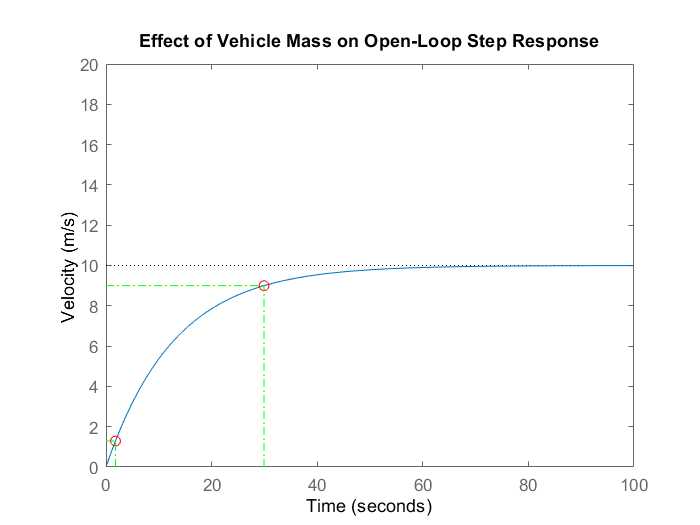

b = 50;
u = 500;
m =650;

P_cruise = 1/(m*s+b);
step(u*P_cruise); 
displayRisetime(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Mass on Open-Loop Step Response')
ylabel('Velocity (m/s)');

disp(["Rise time is " + num2str(stepinfo(u*P_cruise).RiseTime) + " s."]);

Rise time is 28.5611 s.


As expected, we see a direct relationship between the vehicle's mass and its time constant. We can even decrease the mass so that the response fits the given criteria. However, is the mass required to meet the criteria realistic? 

**Damping Coefficient**

From our earlier investigation, we saw that the vehicle parameter $b$ also affects the system's time constant. Since $\tau$ equals $\frac{m}{b}$, increasing the damping coefficient $b$ should reduce the vehicle's time constant in much the same manner as reducing $m$ did. Experiment with the following interactive slider to observe the effect of manipulating the damping coefficient.

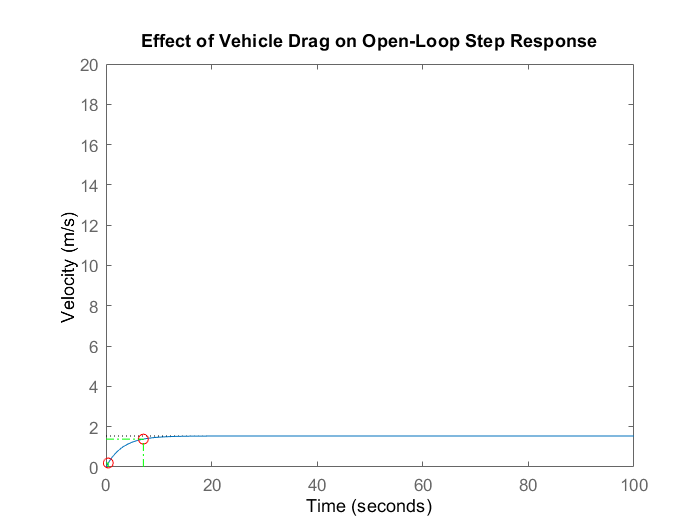

m = 1000;
u = 500;
b = 325; 

P_cruise = 1/(m*s+b);
step(u*P_cruise);
displayRisetime(u*P_cruise); 
axis([0 100 0 20]);
title('Effect of Vehicle Drag on Open-Loop Step Response');
ylabel('Velocity (m/s)');

disp(["Rise time is " + num2str(stepinfo(u*P_cruise).RiseTime) + " s."]);

Rise time is 6.76 s.


As expected, if $b$ is made large enough, we can achieve a rise time of less than 5 seconds. However, the steady-state speed is reduced significantly because the damping coefficient also affects the system's DC gain, $k_{\textrm{dc}}$ = $\frac{1}{b}$. In this model, the damping corresponds to the air drag force applied to the vehicle. Therefore, making the vehicle less aerodynamic allows the vehicle to reach steady state more quickly, but only because its top speed is reduced. Consider if this is a design choice you would like to make.

**Step Input**

In addition to altering the mass and aerodynamics of the vehicle, we can also affect its performance by changing the input, $u$. In practice, this would correspond to altering the vehicle's drivetrain.

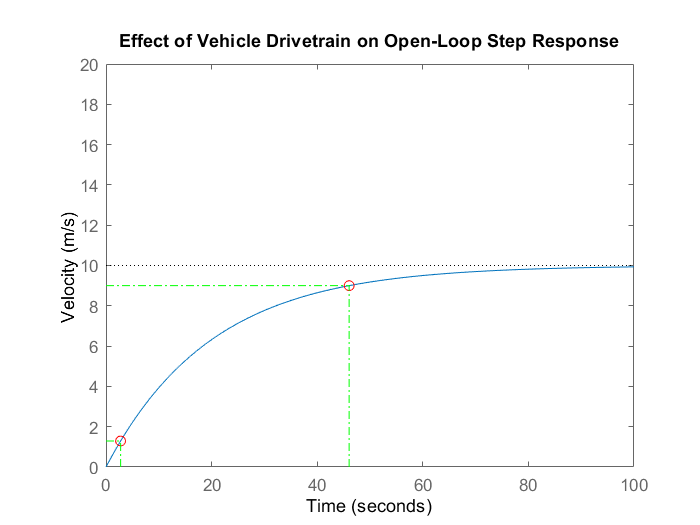

m = 1000;
b = 50;
u = 500;

P_cruise = 1/(m*s+b);
step(u*P_cruise);
displayRisetime(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Drivetrain on Open-Loop Step Response');
ylabel('Velocity (m/s)');

disp(["The Rise time is " + num2str(stepinfo(u*P_cruise).RiseTime) + " s."]);

The Rise time is 43.9401 s.


The effect of changing the magnitude of the step input can be observed as simply scaling the vehicle's output. In this respect, we can make the vehicle reach a higher top speed, but it won't affect how quickly it reaches this steady-state speed. The time constant is unaffected. The modifications to the drivetrain needed to achieve this larger input would also likely make the more vehicle more expensive, heavier, and possibly less fuel efficient.

In conclusion, changing the values of mass, damping coefficient, and step input will not meet the given requirements for realistic parameter values. Therefore, we need to add a controller to the system to speed up the response significantly without negatively affecting the other dynamic performance metrics. This is the subject of the remaining pages of the Cruise Control example.

*The following function is used in the script above.*

function displayRisetime(sys) 
hold on;
[y,t] = step(sys);
%stepResults = stepinfo(y,t);
indexRise10 = find(y >= y(end)*0.1,1);
indexRise90 = find(y >= y(end)*0.9,1);
plot(t(indexRise10),y(indexRise10),'ro');
plot(t(indexRise90),y(indexRise90),'ro');
plot([0 t(indexRise10)],[y(indexRise10) y(indexRise10)],'g-.');
plot([t(indexRise10) t(indexRise10)],[0 y(indexRise10)],'g-.');
plot([0 t(indexRise90)],[y(indexRise90) y(indexRise90)],'g-.');
plot([t(indexRise90) t(indexRise90)],[0 y(indexRise90)],'g-.');
hold off;
end